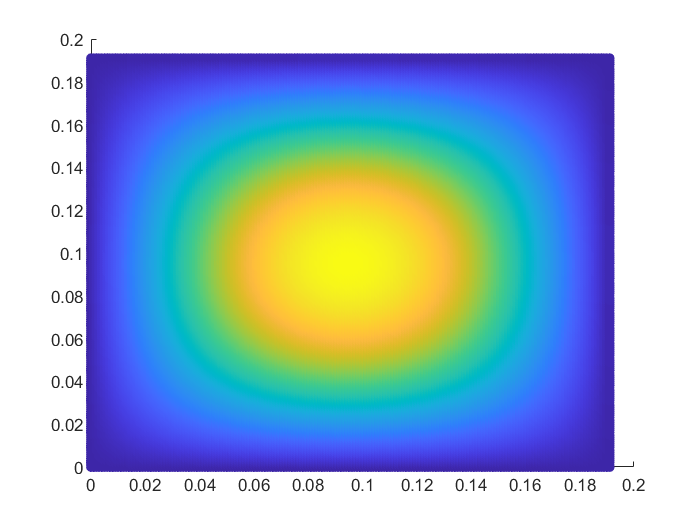

num=textread('nfix.txt'); 
x=num(:,1);y=num(:,2);z=num(:,3);
tri = delaunay(x,y);
tricontour(tri,x,y,z,-6:6);
hold on;
scatter(x,y,[],z,'filled');

function [c,h]=tricontour(tri,x,y,z,nv)
%TRICONTOUR Triangular Contour Plot.
% TRICONTOUR(TRI,X,Y,Z,N) draws scalar N contour lines treating the values
% in Z as heights above a plane. TRI,X,Y,and Z define a triangulation where
% the triangles are defined by the M-by-3 face matrix TRI, such as that
% returned by DELAUNAY. Each row of TRI contains indices into the X,Y, and
% Z vertex vectors to define a single triangular face. Contours are
% computed directly from the triangulation rather than interpolating back
% to a cartesian grid using GRIDDATA.
% TRICONTOUR(TRI,X,Y,Z,V) draws length(V) contour lines at the values
% specified in vector V.
% TRICONTOUR(TRI,X,Y,Z,[v v]) draws a single contour line at the level v.
%
% [C,H] = TRICONTOUR(...) returns contour matrix C as described in CONTOURC
% and a vector of handles H to the created patch objects.
% H can be used to set patch properties.
% CLABEL(C) or CLABEL(C,H) labels the contour levels.
%
% Example:
%           x=linspace(-3,3,39);
%           y=linspace(-2.5,2.5,49);
%           [xx,yy]=meshgrid(x,y);
%           zz=peaks(xx,yy);
%           v=-3:1:5; % contour levels
%           subplot(1,2,1)
%           [C,h]=contour(xx,yy,zz,v);   % standard contour for comparison
%           clabel(C)
%           title Contour
% 
%           idx=randperm(numel(zz));     % grab some scattered indices
%           n=idx(1:ceil(numel(zz)/2))'; % one half of them
%           x=xx(n);                     % get scattered data
%           y=yy(n);
%           z=zz(n);
%           tri=delaunay(x,y);           % triangulate scattered data
%           subplot(1,2,2)
%           [C,h]=tricontour(tri,x,y,z,v);
%           clabel(C,h)
%           title TriContour
%
% view(3) displays the contour in 3-D.
%
% See also DELAUNAY, CONTOUR, TRIMESH, TRISURF, TRIPLOT, PATCH.

% D.C. Hanselman, University of Maine, Orono, ME 04469
% MasteringMatlab@yahoo.com
% Mastering MATLAB 7
% 2006-05-07, 2006-05-16, 2006-07-25

if nargin<5
	error('Not Enough Input Arguments.')
end
x=x(:);	% convert input data into column vectors
y=y(:);
z=z(:);
xlen=length(x);
if ~isequal(xlen,length(y),length(z))
   error('X, Y, and Z Must Have the Same Number of Elements.')
end
if size(tri,2)~=3 || any(tri(:)<0) || any(tri(:)>xlen)
   error('TRI Must Be a Valid Triangulation of the Data in X, Y, Z.')
end

zs=z(tri);
zmax=max(max(zs));              % find max and min in z data that is in tri
zmin=min(min(zs));

if length(nv)==1                                 % nv is number of contours
   zlev=linspace(zmax,zmin,nv+2);
elseif length(nv)==2 && nv(1)==nv(2)              % nv is one contour level
   zlev=nv(1);
else                                       % nv is vector of contour levels
   zlev=sort(nv,'descend');
end
zlev(zlev>=zmax | zlev<=zmin)=[];  % eliminate contours outside data limits
nlev=length(zlev);

if nlev==0
   error('No Contours to Plot. Chosen Contours Outside Limits of Data.')
end

% precondition the input data
[zs,zidx]=sort(zs,2);         % sort vertices by z value ascending
for k=1:size(zs,1)            % shuffle triangles to match
   tri(k,:)=tri(k,zidx(k,:));
end

hax=newplot;                  % create new axis if needed
h=[];                         % patch handle storage
C=zeros(2,0);                 % Clabel data storage
cs=[2 1];                     % column swap vector cs(1)=2, cs(2)=1;

% Main Loop ---------------------------------------------------------------
for v=1:nlev                  % one contour level at a time
   zc=zlev(v);                % chosen level
   above=zs>=zc;              % true for vertices above given contour
   numabove=sum(above,2);     % number of triangle vertices above contour
   tri1=tri(numabove==1,:);   % triangles with one vertex above contour
   tri2=tri(numabove==2,:);   % triangles with two vertices above contour
   n1=size(tri1,1);           % number with one vertex above
   n2=size(tri2,1);           % number with two vertices above

   edge=[tri1(:,[1 3])        % first column is indices below contour level
         tri1(:,[2 3])        % second column is indices above contour level
         tri2(:,[1 2])
         tri2(:,[1 3])];
   if n1==0                   % assign edges to triangle number
      n=[1:n2 1:n2]';
   elseif n2==0
      n=[1:n1 1:n1]';
   else
      n=[1:n1 1:n1 n1+(1:n2) n1+(1:n2)]';
   end

   [edge,idx]=sortrows(edge);    % put shared edges next to each other
   n=n(idx);                     % shuffle triangle numbers to match

   idx=all(diff(edge)==0,2);     % find shared edges
   idx=[idx;false]|[false;idx];  % True for all shared edges
   
   % eliminate redundant edges, two triangles per interior edge
   edgeh=edge(~idx,:);           % hull edges
   nh=n(~idx);                   % hull triangle numbers
   if ~isempty(nh)
      nh(end,2)=0;               % zero second column for hull edges
   end
   edges=edge(idx,:);            % shared edges
   edges=edges(1:2:end-1,:);     % take only unique edges
   ns=n(idx);                    % interior triangle numbers
   ns=[ns(1:2:end) ns(2:2:end)]; % second column is second triangle
   edge=[edgeh;edges];           % unique edges
   nn=[nh;ns];                   % two columns of triangle numbers
   ne=size(edge,1);              % number of edges
   
   flag=true(ne,2);              % true for each unused edge per triangle
   tmp=zeros(ne+1,1);            % contour data temporary storage
   
   xe=x(edge);                   % x values at vertices of edges
   ye=y(edge);                   % y values at  vertices of edges
   ze=z(edge);                   % z data at  vertices of edges

   alpha=(zc-ze(:,1))./(ze(:,2)-ze(:,1)); % interpolate all edges
   xc=alpha.*(xe(:,2)-xe(:,1)) + xe(:,1); % x values on this contour
   yc=alpha.*(ye(:,2)-ye(:,1)) + ye(:,1); % y values on this contour

   while any(flag)	% while there are still unused edges -----------------
      
      xtmp=tmp;
      ytmp=tmp;
      [ir,ic]=find(flag,1);            % find next unused edge
      flag(ir,ic)=false;               % mark this edge used
      
      k=1;                             % first data point in subcontour
      xtmp(k)=xc(ir);                  % store data from this edge
      ytmp(k)=yc(ir);
      
      while true     % complete this subcontour ---------------------------
         
         [ir,ic]=find(flag&nn(ir,ic)==nn,1);% find other edge of triangle
         flag(ir,ic)=false;            % mark this edge used
         k=k+1;
         xtmp(k)=xc(ir);               % store data from this edge
         ytmp(k)=yc(ir);
         
         ic=cs(ic);                    % other triangle that shares edge

         if nn(ir,ic)==0               % reached hull, subcontour complete
            k=k+1;
            xtmp(k)=nan;               % don't let subcontour close
            ytmp(k)=nan;
            break
         elseif ~flag(ir,ic)           % complete closed subcontour
            break
         else                          % more points remain on subcontour
            flag(ir,ic)=false;         % mark this edge used
         end
      end % while true ----------------------------------------------------
      xtmp(k+1:end)=[];                % throw away unused storage
      ytmp(k+1:end)=[];                % xtmp,ytmp contain subcontour
      
      if nargout<2                     % plot the subcontour
         patch('XData',xtmp,'YData',ytmp,'CData',repmat(zc,k,1),...
               'Parent',hax,'FaceColor','none','EdgeColor','flat',...
               'UserData',zc)
         C=horzcat(C,[zc xtmp';k ytmp']); % contour label data
      else                             % plot subcontour and create output
         h=[h;patch('XData',xtmp,'YData',ytmp,'CData',repmat(zc,k,1),...
         'Parent',hax,'FaceColor','none','EdgeColor','flat',...
         'UserData',zc)]; %#ok
         C=horzcat(C,[zc xtmp';k ytmp']); % contour label data
      end
   end % while any(flag) --------------------------------------------------
end % for v=1:nlev
if nargout
   c=C;
end
end